%TODO: 
% 1. Mark removed outofscope windows in UI
% 3. Check Vibro
clear;
signalType = "Vibro";
if (signalType == 'Current')
    % Load dataset
    datasetName = "dataset5";
    files = metadata.selectPreset(metadata.collect('DataSet'), datasetName);

    pipeline_opt = struct();

    %pipeline_opt.exclude = features.registry('currents_w_park');
    pipeline_opt.windowOverlap = 0;
    %pipeline_opt.exclude = ["Mean_A", "Mean_B", "Std_A", "Std_B"];
    %pipeline_opt.exclude = ["DominantFreq_A", "Std_A"];
%    pipeline_opt.exclude = ["Mean_B", "Ellipse_Offset", "RMS_A", "Std_A", "Mean_A", "SpecEnergy_A", "Std_P", "Std_A", "Std_B"];
%     pipeline_opt.exclude = ["Mean_A", ...
%         "Mean_B", ...
%         "Std_A", ...
%         "Std_B", ...
%         "DominantFreq_A", ...
%         "DominantFreq_B", ...
%         "DominantFreq_P", ...
%         "RMS_A", ... // corr with RMS_Vector_Mag
%         "RMS_B", ... // corr with RMS_Vector_Mag
%         "RMS_VectorMag", ... // corr with RMS_P
%         "SpecEnergy_A", ... // corr with RMS_P
%         "SpecEnergy_B", ... // corr with RMS_P
%         "SpecEnergy_P", ... // corr with RMS_P
%         "Mean_P", ... // corr with RMS_P,
%         "Skew_P", ... // corr with Curt_P,
%         "Ellipse_A", ... // corr with RMS_P
%         "Ellipse_B", ... // corr with RMS_P
%         "Entropy_P", ... // corr with Centroid_P
%         "Ellipse_PhiDeg", ...
%         "Ellipse_Ratio", ...
%         "Ellipse_Ecc", ...
%         "Skew_A", ... // corr with Curt_P,
%         "Skew_B", ... // corr with Curt_P,
%         "Entropy_B", ... // corr with Curt_P,
%         "Kurt_A", ... // corr with Curt_P,
%         "Entropy_A", ... // corr with Curt_P,
%         "Kurt_B", ... // corr with Curt_P,
%         "Std_P"...
%         ];
    %reg_opt.vibroChannels = [1 2 3 4];
    reg_opt.phaseA = true;
    reg_opt.phaseB = true;
    reg_opt.timeDomain = true;
    reg_opt.freqDomain = true;
    %reg_opt.crossPhase = true;
    %reg_opt.park = true;
    pipeline_opt.include = features.registry(reg_opt)
%     pipeline_opt.include = [ ...
%     "RMS_P", ...
%     "Centroid_P", ...
%     "PTP_A", ...
%     "PTP_B", ...
%     "Kurt_B", ...
%     "Kurt_P", ...
%     "Entropy_A", ...
%     "Entropy_B", ...
%     "Centroid_A", ...
%     "Centroid_B" ...
% ];
elseif signalType == 'Vibro'
    % VIBRO

    % Load dataset
    datasetName = "dataset25";
    files = metadata.selectPreset(metadata.collect('DataSet'), datasetName);

    pipeline_opt = struct();

    %pipeline_opt.exclude = features.registry('currents_w_park');
    pipeline_opt.windowOverlap = 0;
    pipeline_opt.exclude = [
        "Std_Ch1", ...
        "Std_Ch2", ...
        "PTP_Ch1", ...
        "PTP_Ch2", ...
        %"SpecEnergy_Ch1", ... // corr with RMS_P
        %"SpecEnergy_Ch2", ... // corr with RMS_P
        %"Entropy_Ch2", ...
        %"Centroid_Ch2", ...
        %"DominantFreq_Ch1", ...
        %"DominantFreq_Ch2"
        ];
    reg_opt.vibroChannels = [1 2];
    reg_opt.timeDomain = true;
    reg_opt.freqDomain = true;
    pipeline_opt.include = features.registry(reg_opt)
end

pipeline_opt = struct with fields:
    windowOverlap: 0
          exclude: ["Std_Ch1"    "Std_Ch2"    "PTP_Ch1"    "PTP_Ch2"]
          include: {1×22 cell}



[X, Y, featureTbl, featureNames, excludedWindows] = features.pipeline(files, pipeline_opt);


rfM = ml.rfMetrics(X, Y, featureNames, ml.makeGroupedCV(featureTbl));

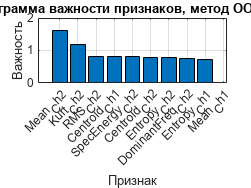


% Plot Feature Importance Bar
figure;
bar(rfM.featureImp(1:9));
title('Диаграмма важности признаков, метод OOB (RF)');
xlabel('Признак');
ylabel('Важность');
xticks(1:length(rfM.featureNames));
xticklabels(rfM.featureNames);
xtickangle(45);
grid on;


% Top features of each class
for c = 1:numel(rfM.perClassLabels)
    [sortedImp, idx] = sort(rfM.perClassFeatureImp(:,c), 'descend');
    fprintf('Top features for class %s:\n', string(rfM.perClassLabels(c)));
    disp(rfM.perClassFeatureNames(idx(1:5))); % Top 5
end

Top features for class faulty bearing:


    {'Entropy_Ch2'}    {'Mean_Ch2'}    {'RMS_Ch2'}    {'SpecEnergy_Ch2'}    {'Mean_Ch1'}



Top features for class healthy:


    {'Entropy_Ch1'}    {'SpecEnergy_Ch1'}    {'RMS_Ch1'}    {'Mean_Ch2'}    {'Kurt_Ch1'}



Top features for class misalignment:


    {'Centroid_Ch1'}    {'Entropy_Ch1'}    {'Mean_Ch1'}    {'Entropy_Ch2'}    {'Mean_Ch2'}



Top features for class system misalignment:


    {'Mean_Ch2'}    {'Kurt_Ch2'}    {'Centroid_Ch2'}    {'Mean_Ch1'}    {'SpecEnergy_Ch2'}



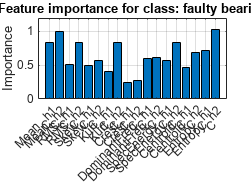

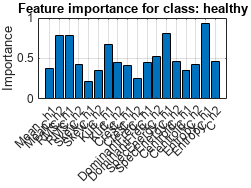

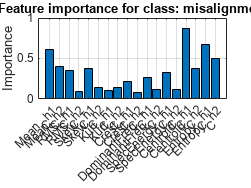

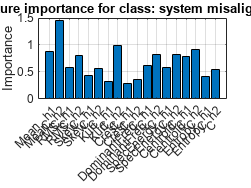


% Per-class imp
for classIdx = 1:length(rfM.perClassLabels) % For the first class
    figure;
    bar(rfM.perClassFeatureImp(:, classIdx));
    set(gca, 'XTick', 1:numel(rfM.perClassFeatureNames), 'XTickLabel', rfM.perClassFeatureNames, 'XTickLabelRotation', 45);
    title(sprintf('Feature importance for class: %s', string(rfM.perClassLabels(classIdx))));
    ylabel('Importance');
    grid on;
end

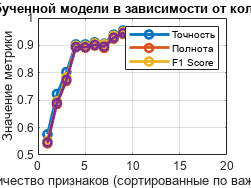

% Plot Metrics vs. Number of Features
figure;
met = [rfM.metrics(:, 1) rfM.metrics(:, 2) rfM.metrics(:, 3) rfM.metrics(:, 4)];
plot(met, '-o', 'LineWidth', 2);
legend('Точность', 'Полнота', 'F1 Score');
xlabel('Количество признаков (сортированные по важности)');
ylabel('Значение метрики');
title('Точность обученной модели в зависимости от кол-ва признаков');
grid on;


% Print Best Metrics + Features
metricNames = ["Accuracy", "Precision", "Recall", "F1 Score"];

for loopIdx = 1:4
    [loopBestVal, loopBestIdx] = max(rfM.metrics(:, loopIdx));
    fprintf('Best %s: %.4f with %d features\n', metricNames(loopIdx), loopBestVal, loopBestIdx);
    disp(rfM.featureNames(1:loopBestIdx)');
end

Best Accuracy: 0.9548 with 9 features


    {'Mean_Ch2'        }
    {'Kurt_Ch2'        }
    {'RMS_Ch2'         }
    {'Centroid_Ch1'    }
    {'SpecEnergy_Ch2'  }
    {'Centroid_Ch2'    }
    {'Entropy_Ch2'     }
    {'DominantFreq_Ch2'}
    {'Entropy_Ch1'     }



Best Precision: 0.9422 with 9 features


    {'Mean_Ch2'        }
    {'Kurt_Ch2'        }
    {'RMS_Ch2'         }
    {'Centroid_Ch1'    }
    {'SpecEnergy_Ch2'  }
    {'Centroid_Ch2'    }
    {'Entropy_Ch2'     }
    {'DominantFreq_Ch2'}
    {'Entropy_Ch1'     }



Best Recall: 0.9499 with 9 features


    {'Mean_Ch2'        }
    {'Kurt_Ch2'        }
    {'RMS_Ch2'         }
    {'Centroid_Ch1'    }
    {'SpecEnergy_Ch2'  }
    {'Centroid_Ch2'    }
    {'Entropy_Ch2'     }
    {'DominantFreq_Ch2'}
    {'Entropy_Ch1'     }



Best F1 Score: 0.9453 with 9 features


    {'Mean_Ch2'        }
    {'Kurt_Ch2'        }
    {'RMS_Ch2'         }
    {'Centroid_Ch1'    }
    {'SpecEnergy_Ch2'  }
    {'Centroid_Ch2'    }
    {'Entropy_Ch2'     }
    {'DominantFreq_Ch2'}
    {'Entropy_Ch1'     }

